%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

cd ..

%SDK AROMA
ppbSDKAROMA = readtimetable("etoAROMA_SDK.xlsx");

cd ../.. %change to data folder

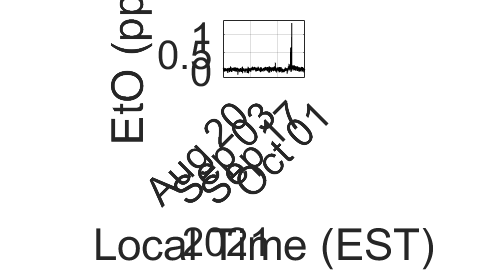

%%%%%%%%%%%%%%%%%%%%%%
%%%plot Picarro data
%%%%%%%%%%%%%%%%%%%%%%
times = ppbSDKPicarro.Properties.RowTimes;
xlims = datetime(2021, [8, 10], [20, 1]);

fig = figure('Position', get(0, 'Screensize')); %for saving the figure
hold on
box on
grid on
pbaspect([1.4, 1, 1])
ax = gca;

plot(times, ppbSDKPicarro.Corrected_EtO, '-k')

%lims
xlim(xlims)
xticks(xlims(1):calweeks(2):xlims(2))
ylim([-0.21, 1.41])

%labels
ax.FontSize = 30;
xlabel("Local Time (EST)")
ylabel("EtO (ppb)")

hold off

%%export the figure
cd ..\Figures
a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
fn = "Figure supplemental peaks.png";
exportgraphics(fig, fn)
delete(a) %make plot interactive again

cd ..\Data

%%%calculate stats
inds = isbetween(times, xlims(1), xlims(end)); %get times in figure
temp = ppbSDKPicarro.Corrected_EtO(inds); %grab relevant data

avg = mean(temp, "omitnan");
stds = std(temp, 0, "omitnan");

%%NOTE: 4 outliers, >0.2

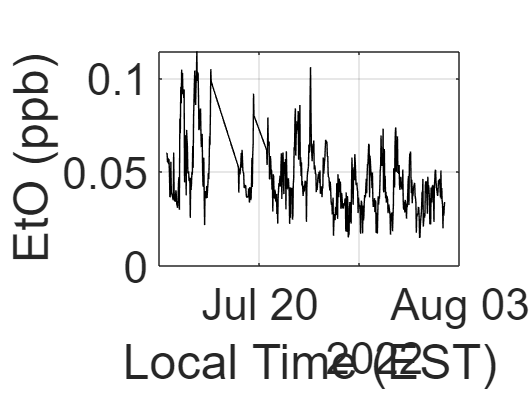

colorAROMA = [0.8392, 0.5686, 0.3098];

%%%%%%%%%%%%%%%%%%%%%%
%%%plot AROMA data
%%%%%%%%%%%%%%%%%%%%%%
times = ppbSDKAROMA.Properties.RowTimes;
% xlims = datetime(2021, [8, 10], [6, 1]);

figure
hold on
box on
grid on
pbaspect([1.4, 1, 1])
ax = gca;

plot(times, ppbSDKAROMA.EtO, '-k')

%lims
% xlim(xlims)
% xticks(xlims(1):calweeks(2):xlims(2))
% ylim([-0.21, 1.41])

%labels
ax.FontSize = 30;
xlabel("Local Time (EST)")
ylabel("EtO (ppb)")

hold off

%%%calculate stats
inds = isbetween(times, xlims(1), xlims(end)); %get times in figure
temp = ppbSDKAROMA.EtO(inds); %grab relevant data

avg = mean(temp, "omitnan");
stds = std(temp, 0, "omitnan");

%%NOTE: 4 outliers, >0.2